clear all
load('L-I-20C.mat')

x_1 = 0.3E-3;
x_2 = 0.5;
x_3 = 2.6E3;
x_4 = 1.246E-3;
x_5 = -2.545E-5;
x_6 = 2.908E-7;
x_7 = -2.531E-10;
x_8 = 1.022E-12;

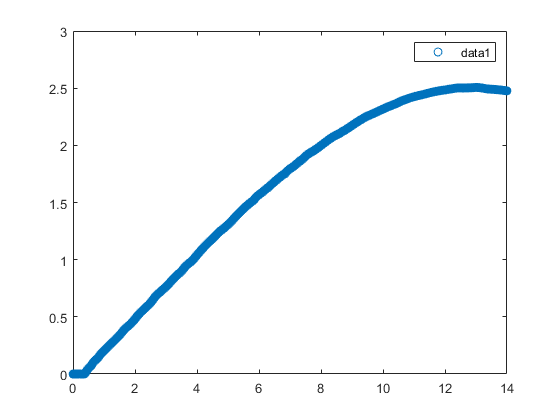

figure 
plot(I, P, 'o')
legend

load('L-I-20C.mat')
P_train = P(39:end);
I_train = I(39:end);
U_train = U(39:end);
s = 0;
for i = 1:length(P_train)    
    s = s + (P_train(i) - x_1*(I_train(i) - x_2 - x_4 - x_5*(20 + x_3*(I_train(i)*U_train(i) - P_train(i))) - x_6*(20 + x_3*(I_train(i)*U_train(i) - P_train(i))).^2 - x_7*(20 + x_3*(I_train(i)*U_train(i) - P_train(i))).^3 - x_8*(20 + x_3*(I_train(i)*U_train(i) - P_train(i))).^4 )).^2;
end
s

s = 1.1436e+11

% y = y + (P_train(i) - x(1)*(I_train(i) - x(2) - x(4) - x(5)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))) - x(6)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^2 - x(7)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^3 - x(8)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^4 )).^2;
% load('L-I-20C.mat')
% P_train = P(39:end)/1000;
% I_train = I(39:end)/1000;
% U_train = U(39:end);
% x = [0.5, 0.3E-3, 2.6E3, 1.246E-3, -2.545E-5, 2.908E-7, -2.531E-10, 1.022E-12];
y = zeros([1, 39]);
for i = 1:length(I_train)
    y(i+38) = 1000*x(1)*(I_train(i) - x(2) - x(4) - x(5)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))) - x(6)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^2 - x(7)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^3 - x(8)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^4 );
end

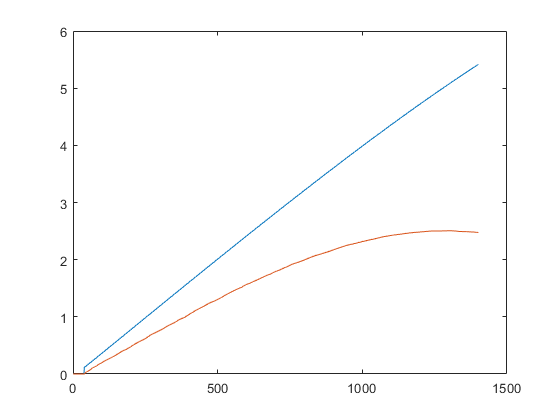

figure
plot(y)
hold on
plot(P)

## 利用fminsearch

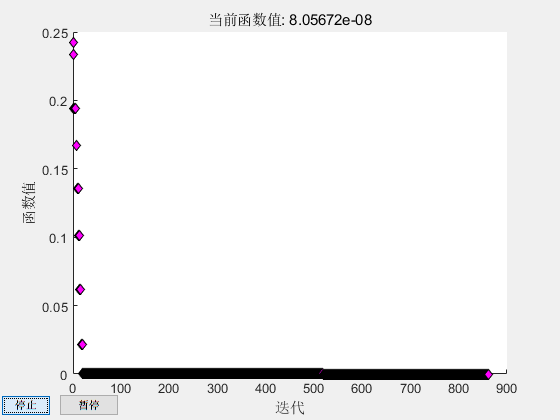

ans = 	1.0e+03 *

    0.0004    0.0000    3.7328    0.0000   -0.0000    0.0000   -0.0000    0.0000


init = [0.5, 0.3E-3, 2.6E3, 1.246E-3, -2.545E-5, 2.908E-7, -2.531E-10, 1.022E-12];
first(init)


y = y + (P_train(i) - x(1)*(I_train(i) - x(2) - x(4) - x(5)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))) - x(6)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^2 - x(7)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^3 - x(8)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^4 )).^2;
load('L-I-20C.mat')
P_train = P(39:end)/1000;
I_train = I(39:end)/1000;
U_train = U(39:end);
x = ans;
y = zeros([1, 39]);
for i = 1:length(I_train)
    y(i+38) = 1000*x(1)*(I_train(i) - x(2) - x(4) - x(5)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))) - x(6)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^2 - x(7)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^3 - x(8)*(68 + x(3)*(I_train(i)*U_train(i) - P_train(i))).^4 );
end

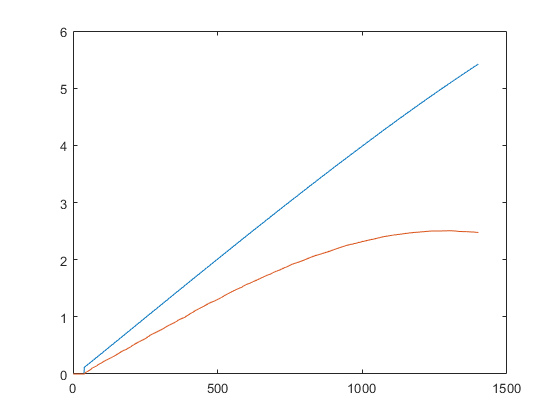

figure
plot(y)
hold on
plot(P')

lower = [0.2, 0.3E-6, 2.6E3, 1E-4, -3E-2, 2.908E-8, -3.531E-2, 5E-13];
upper = [0.5, 0.3E-2, 4E3, 4E-3, -1.5E-5, 2.908E-2, -1.531E-10, 7E-2];
upper- lower
x - lower
upper - x
-2.531E-10 - 1E-10

ans = -3.5310e-10

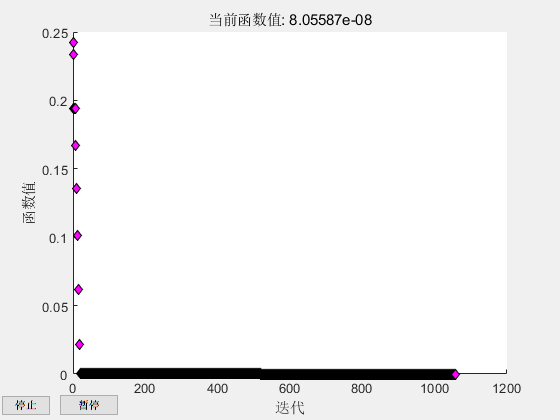

x = 	1.0e+03 *

    0.0004    0.0000    3.7572    0.0000   -0.0000    0.0000   -0.0000    0.0000


t = [30, 35, 32.5, 31.25, 30.625, 30.3125, 30.4688];
t = [10, 20, 30, 40, 50, 60, 70, 80, 90];
f = t + 273.15;
init = [0.5, 0.3E-3, 2.6E3, 1.246E-3, -2.545E-5, 2.908E-7, -2.531E-10, 1.022E-12];
x = first(init)

t = [20]

t = 20

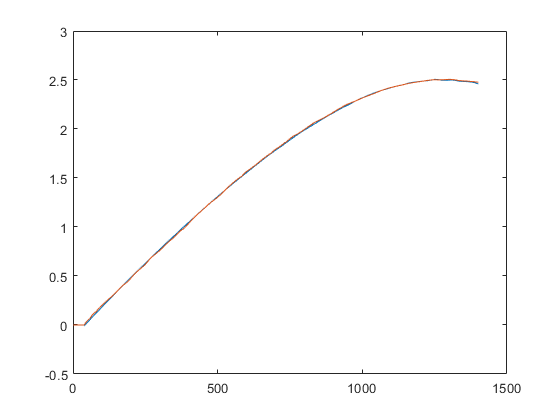

f = t + 273.15;
load('L-I-20C.mat')
P_train = P(39:end)/1000;
I_train = I(39:end)/1000;
U_train = U(39:end);
figure
for j = 1:1
    y = zeros([1, 39]);
    for i = 1:length(I_train)
        y(i+38) = 1000*x(1)*(I_train(i) - x(2) - x(4) - x(5)*(f(j) + x(3)*(I_train(i)*U_train(i) - P_train(i))) - x(6)*(f(j) + x(3)*(I_train(i)*U_train(i) - P_train(i))).^2 - x(7)*(f(j) + x(3)*(I_train(i)*U_train(i) - P_train(i))).^3 - x(8)*(f(j) + x(3)*(I_train(i)*U_train(i) - P_train(i))).^4 );
    end

    plot(y)
    hold on
end
% legend('10', '20', '30', '40', '50', '60', '70', '80', '90');
% y_1=[0, 1500];
% y_2=[2, 2];
% plot(y_1,y_2,'linewidth',1.5)
plot(P)

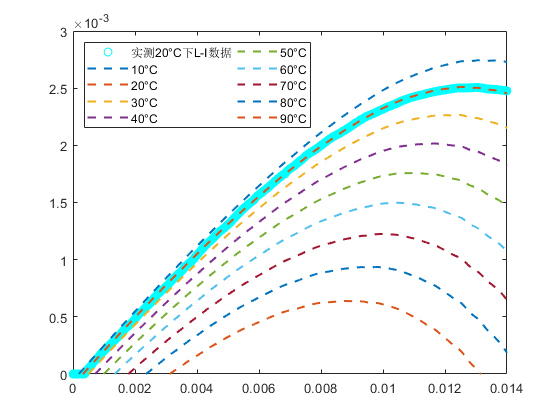

t = [10, 20, 30, 40, 50, 60, 70, 80, 90];
f = t + 273.15;
load('L-I-20C.mat')
P = P/1000;
I = I/1000;
U = U;
figure
plot(I, P, 'oc')
hold on
for j = 1:9

    T = f(j);
    y = x(1).*(I - x(2) - x(4) - x(5).*(T + (I.*U - P).*x(3) ) - x(6).*(T + (I.*U - P).*x(3) ).^2 - x(7).*(T + (I.*U - P).*x(3) ).^3 - x(8).*(T + (I.*U - P).*x(3) ).^4);

    plot(I, y, '--', 'linewidth',1.5)
    hold on
end
legend({'实测20°C下L-I数据', '10°C', '20°C', '30°C', '40°C', '50°C', '60°C', '70°C', '80°C', '90°C'}, 'Location','northwest','NumColumns',2);
axis([0 0.014 0 3e-3])
saveas(gcf, 'fig3.png');

% y_1=[0, 1500];
% y_2=[2, 2];
% plot(y_1,y_2,'linewidth',1.5)

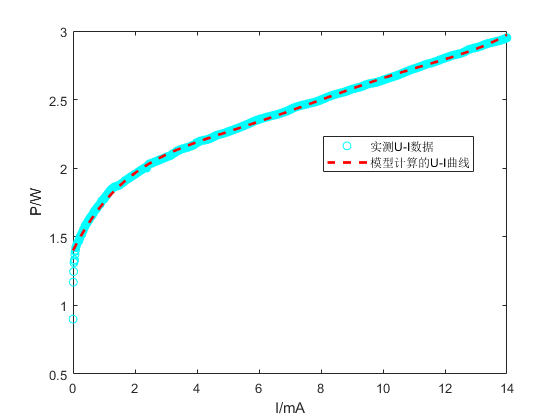

load('L-I-20C.mat')
P = P/1000;
% I = I/1000;
U = U;
init = [1 0.5 -0.3 0.03 -6e-4 5e-5];
% init = [1.400131039196883 0.442357171224129 -0.104988380399638 0.014248010889581 -9.150132320360773e-04 2.233431354694871e-05];
c = optimresults.x;
% c = init;
Ui = c(1) + c(2).*I + c(3).*I.^2 + c(4).*I.^3 + c(5).*I.^4 + c(6).*I.^5;
figure
plot(I, U, 'oc')
hold on
plot(I, Ui, 'r--', 'LineWidth',2)
xlabel('I/mA')
ylabel('P/W')
legend({'实测U-I数据', '模型计算的U-I曲线'}, 'Location','best')

% saveas(gcf, 'fig4.png');

t = [10, 20, 30, 40, 50, 60, 70, 80, 90];
f = t + 273.15;
load('L-I-20C.mat')
P = P/1000;
I = I/1000;
U = U;
figure
plot(I, P, 'oc')
hold on
for j = 1:9

    T = f(j);
    y = x(1).*(I - x(2) - x(4) - x(5).*(T + (I.*U - P).*x(3) ) - x(6).*(T + (I.*U - P).*x(3) ).^2 - x(7).*(T + (I.*U - P).*x(3) ).^3 - x(8).*(T + (I.*U - P).*x(3) ).^4);
    ymax(j) = max(y);
    plot(I, y, '--', 'linewidth',1.5)
    hold on
end
legend({'实测20°C下L-I数据', '10°C', '20°C', '30°C', '40°C', '50°C', '60°C', '70°C', '80°C', '90°C'}, 'Location','northwest','NumColumns',2);
axis([0 0.014 0 3e-3])

ymax

ymax =     0.0027    0.0025    0.0023    0.0020    0.0018    0.0015    0.0012    0.0009    0.0006


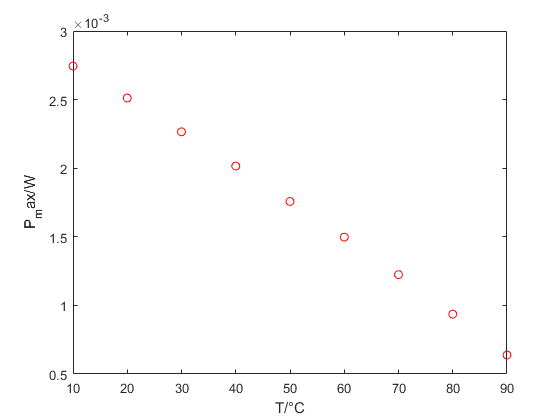

figure
plot(t, ymax, 'or')
xlabel('T/°C')
ylabel('P_max/W')
saveas(gcf, 'fig6.png');

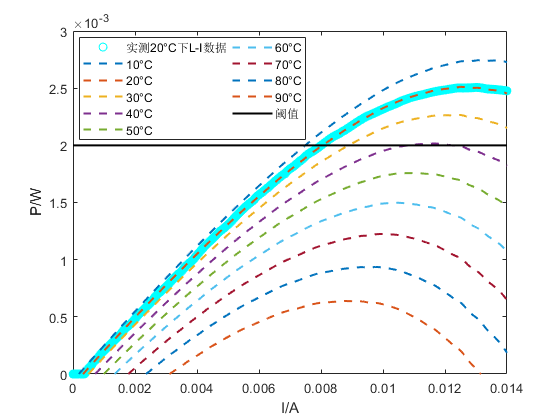

t = [10, 20, 30, 40, 50, 60, 70, 80, 90];
f = t + 273.15;
load('L-I-20C.mat')
P = P/1000;
I = I/1000;
U = U;
figure
plot(I, P, 'oc')
hold on
for j = 1:9

    T = f(j);
    y = x(1).*(I - x(2) - x(4) - x(5).*(T + (I.*U - P).*x(3) ) - x(6).*(T + (I.*U - P).*x(3) ).^2 - x(7).*(T + (I.*U - P).*x(3) ).^3 - x(8).*(T + (I.*U - P).*x(3) ).^4);

    plot(I, y, '--', 'linewidth',1.5)
    hold on
end
axis([0 0.014 0 3e-3])
y_1=[0, 0.014];
y_2=[2e-3, 2e-3];
plot(y_1,y_2, 'k', 'linewidth',1.5)
legend({'实测20°C下L-I数据', '10°C', '20°C', '30°C', '40°C', '50°C', '60°C', '70°C', '80°C', '90°C', '阈值'}, 'Location','best','NumColumns',2);
xlabel('I/A')
ylabel('P/W')
saveas(gcf, 'fig8.png');

## 二分法求临界温度

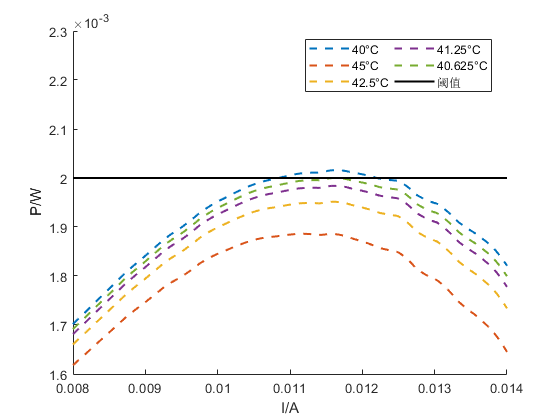

load('L-I-20C.mat')
t = [40, 45, 42.5, 41.25, 40.625];
f = t + 273.15;
load('L-I-20C.mat')
P = P/1000;
I = I/1000;
U = U;
figure
% plot(I, P, 'oc')
hold on
for j = 1:length(t)

    T = f(j);
    y = x(1).*(I - x(2) - x(4) - x(5).*(T + (I.*U - P).*x(3) ) - x(6).*(T + (I.*U - P).*x(3) ).^2 - x(7).*(T + (I.*U - P).*x(3) ).^3 - x(8).*(T + (I.*U - P).*x(3) ).^4);

    plot(I, y, '--', 'linewidth',1.5)
    hold on
end
axis([0.008 0.014 1.6e-3 2.3e-3])
y_1=[0, 0.014];
y_2=[2e-3, 2e-3];
plot(y_1,y_2, 'k', 'linewidth',1.5)
legend({'40°C', '45°C', '42.5°C', '41.25°C', '40.625°C', '阈值'}, 'Location','best','NumColumns',2);
% legend({'实测20°C下L-I数据', '10°C', '20°C', '30°C', '40°C', '50°C', '60°C', '70°C', '80°C', '90°C', '阈值'}, 'Location','best','NumColumns',2);
xlabel('I/A')
ylabel('P/W')
saveas(gcf, 'fig9.png');

ini = [57.8 0.15 1.5e-8];

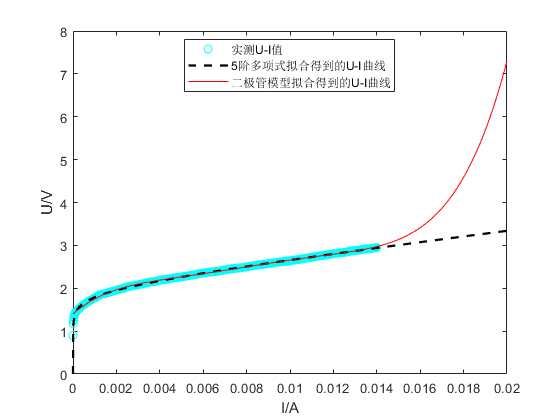

x = optimresults1.x;
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
T = 273.15 + 20;
P = P./1000;
figure
plot(I./1000, U, 'oc')
I = 0:1e-5:0.02;
Un = I.*x(1) + x(2).*log(1 + I./x(3));
hold on
plot(I, Un, '--k', 'LineWidth',1.7)

x = optimresults.x;
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
T = 273.15 + 20;
P = P./1000;
% I = I./1000;
I = 0:1e-5:0.02;
I = I.* 1000;
Un1 = c(1) + c(2).*I + c(3).*I.^2 + c(4).*I.^3 + c(5).*I.^4 + c(6).*I.^5;
hold on
plot(I./1000, Un1, 'r')
xlabel('I/A')
ylabel('U/V')
legend({'实测U-I值', '5阶多项式拟合得到的U-I曲线', '二极管模型拟合得到的U-I曲线'}, 'Location','best')
saveas(gcf, 'fig10.png');

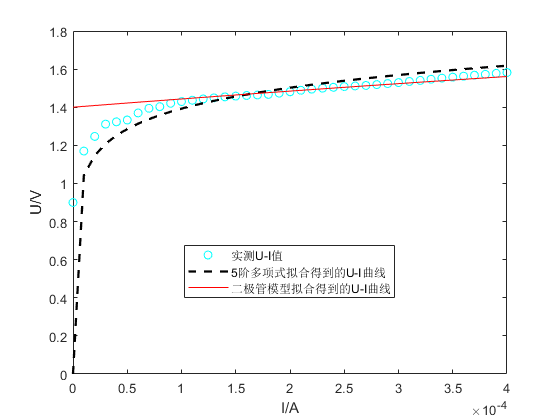

x = optimresults1.x;
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
T = 273.15 + 20;
P = P./1000;
U = U(1:41);
I = I(1:41)./1000;
figure
plot(I, U, 'oc')
Un = I.*x(1) + x(2).*log(1 + I./x(3));
hold on
plot(I, Un, '--k', 'LineWidth',1.7)

x = optimresults.x;
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
T = 273.15 + 20;
P = P./1000;
% I = I./1000;
U = U(1:41);
I = I(1:41);
Un1 = c(1) + c(2).*I + c(3).*I.^2 + c(4).*I.^3 + c(5).*I.^4 + c(6).*I.^5;
hold on
plot(I./1000, Un1, 'r')
xlabel('I/A')
ylabel('U/V')
legend({'实测U-I值', '5阶多项式拟合得到的U-I曲线', '二极管模型拟合得到的U-I曲线'}, 'Location','best')
saveas(gcf, 'fig11.png');

load('S21_5.mat')
F = f(1138:end);
Hf = S21(1138:end);
P_train = P(39:end)/1000;
I_train = I(39:end)/1000;
U_train = U(39:end);
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.324413652820912;
q = 1.6E-19;
Ith0 = 0.000219244267062602;
Rth = 3.249149910157457e+03;
a_0 = 0.000745355211885121;
a_1 = -2.70751304651695e-05;
a_2 = 2.76422683018535e-07;
a_3 = -2.22732107765099e-10;
a_4 = 1.34775894084846e-12;
T =  293.15 + (I_train.*U_train - P_train).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
x = init;
Ns = (P_train./(x(4).*x(7)) + x(5).*x(6).*P_train./(x(4) + x(8).*P_train))./(x(2)./x(3) + x(5).*P_train./(x(4) + x(8).*P_train));
test1 = q./x(1).*(Ns./x(3) + x(5).*(Ns - x(6)).*P_train./(x(4) + x(8).*P_train)) + Ith0 + Ioff - I_train

test1 =     0.0212
    0.0212
    0.0212
    0.0212
    0.0213
    0.0213
    0.0213
    0.0213
    0.0213
    0.0213


% test1 = test1./(I_train)

Ss = ((x(1).*(I_train - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = x(4).*Ss - P_train

test2 =    -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053


% test2 = test2./P_train

Ns1 = (1.904172485e-3./(x(4).*x(7)) + x(5).*x(6).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3))./(x(2)./x(3) + x(5).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3));
T1 = 293.15 + (7.5e-3.*2.464597008 - 1.904172485e-3).*Rth;
Ioff1 = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ss1 = ((x(1).*(7.5e-3 - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
Ps1 = x(4).*Ss1;
C = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方

A = (Z.^2 - 4.*pi.^2.*F.^2.*Z)./(Z.^2 - 8.*pi.^2.*F.^2.*Z + 16.*pi.^4.*F.^4 - 4.*pi.^2.*F.^2.*C.^2);
B = 2.*pi.*F.*Z.*C./(Z.^2 - 8.*pi.^2.*F.^2.*Z + 16.*pi.^4.*F.^4 - 4.*pi.^2.*F.^2.*C.^2);
HF = sqrt(A.^2 + B.^2);
test3 = HF - exp(Hf/10)

test3 =     0.0908
    0.0910
    0.0913
    0.0916
    0.0918
    0.0921
    0.0923
    0.0926
    0.0928
    0.0931


% test3 = test3./(Hf);
y2 = sum(test1.^2 + test2.^2 + test3.^2)

y2 = 471.1088

load('S21_5.mat')
F = f(1138:end)*1e9;
Hf = S21(1138:end);
P_train = P(39:end)/1000;
I_train = I(39:end)/1000;
U_train = U(39:end);
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.324413652820912;
q = 1.6E-19;
Ith0 = 0.000219244267062602;
Rth = 3.249149910157457e+03;
a_0 = 0.000745355211885121;
a_1 = -2.70751304651695e-05;
a_2 = 2.76422683018535e-07;
a_3 = -2.22732107765099e-10;
a_4 = 1.34775894084846e-12;
T =  293.15 + (I_train.*U_train - P_train).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
x = init;
Ns = (P_train./(x(4).*x(7)) + x(5).*x(6).*P_train./(x(4) + x(8).*P_train))./(x(2)./x(3) + x(5).*P_train./(x(4) + x(8).*P_train));
test1 = q./x(1).*(Ns./x(3) + x(5).*(Ns - x(6)).*P_train./(x(4) + x(8).*P_train)) + Ith0 + Ioff - I_train

test1 =     0.0212
    0.0212
    0.0212
    0.0212
    0.0213
    0.0213
    0.0213
    0.0213
    0.0213
    0.0213


% test1 = test1./(I_train)

Ss = ((x(1).*(I_train - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = x(4).*Ss - P_train

test2 =    -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053
   -0.0053


% test2 = test2./P_train

Ns1 = (1.904172485e-3./(x(4).*x(7)) + x(5).*x(6).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3))./(x(2)./x(3) + x(5).*1.904172485e-3./(x(4) + x(8).*1.904172485e-3));
T1 = 293.15 + (7.5e-3.*2.464597008 - 1.904172485e-3).*Rth;
Ioff1 = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ss1 = ((x(1).*(7.5e-3 - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
Ps1 = x(4).*Ss1;
C = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方

A = (Z.^2 - 4.*pi.^2.*F.^2.*Z)./(Z.^2 - 8.*pi.^2.*F.^2.*Z + 16.*pi.^4.*F.^4 - 4.*pi.^2.*F.^2.*C.^2);
B = 2.*pi.*F.*Z.*C./(Z.^2 - 8.*pi.^2.*F.^2.*Z + 16.*pi.^4.*F.^4 - 4.*pi.^2.*F.^2.*C.^2);
HF = sqrt(A.^2 + B.^2);
test3 = HF - exp(Hf/10)

test3 =    -0.9723
   -0.9721
   -0.9720
   -0.9719
   -0.9718
   -0.9717
   -0.9716
   -0.9714
   -0.9713
   -0.9712


% test3 = test3./(Hf);
y2 = sum(test1.^2 + test2.^2 + test3.^2)

y2 = 858.4698

fitness_2(init)

ans = 471.1088

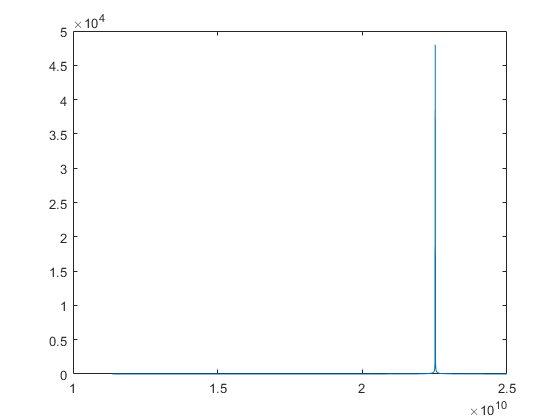

figure
plot(F, HF)

options = optimset('fminsearch');
options.TolX = 1000000;
fminsearch(@fitness_2, init, options)

ans = 	1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    1.8000    0.4970    0.0000    0.0000


ans =     0.9723
    0.9721
    0.9720
    0.9719
    0.9718
    0.9717
    0.9716
    0.9714
    0.9713
    0.9712
